# Practica P01 

Integrantes:

- Juarez Barrios Baruch Isaac

- Cruz del Angel Maria de los Angeles

- Ibarra Cruz Marco Antonio

- Romero Valencia John Benjamín

**Contenidos de la Practica (Entregables)**

**• ENTREGABLE INTRODUCCION - Graficando con Python **

**Foto → Grafica Problema 4  **

[Link a Codigo Python](https://colab.research.google.com/drive/1hdOq_L9Of9sase9CceBcPl_A1aicKSRz?usp=sharing)

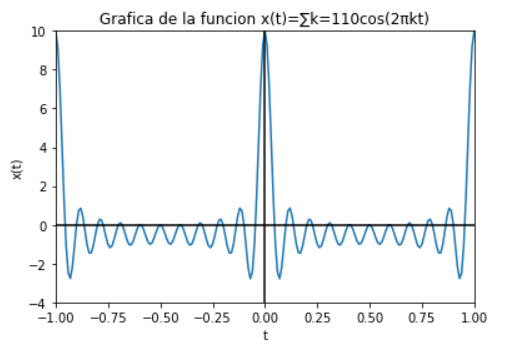**• ENTREGABLE 1 - Seccion 1.1 Lathi → Funciones Anonimas y Graficas en Matlab**

Muchas de las funciones son fecuentemente representadas utilizando **Funciones anonimas de Matlab , **esto permite una representacion simbolica de la funcion definida en terminos de opreadores matematicos y otras funciones de Matlab por ejemplo:

**Dada la funcion :**


$${\mathit{\mathbf{f}}\left(t\right)\;=\;\mathit{\mathbf{e}}}^{-\mathit{\mathbf{t}}} \cos \left(2\pi \mathit{\mathbf{t}}\right)\;$$


**Realizar el codigo necesario para ingresar a f(t) como una funcion anonima en funcion de la variable t : **

La sintaxis para  ingresar una funcion dependiente de una variable es la siguente:

f = @(t) exp(-t).*cos(2*pi*t)

f = function_handle with value:
    @(t)exp(-t).*cos(2*pi*t)


Una vez creada la funcion podemos evaluarla simplemente pasando valores a el argumento de la funcion, para realizar esto tenemos dos opciones:

- Damos valor especifico a t, por ejemplo **t = 0 o f(0)**

t = 0; f(t)

ans = 1

f(0)

ans = 1

Lo anterior compruea que ambos metodos son exactamente lo mismo

- Evaluamos en f(t) con un conjunto de valores **Vector**

Si definimos t como vector, lo podemos aprovechar para hacer una grafica con t y f(t)

t = (-2:2);
% La operacion anterior definio a t con los valores de -2,-1,0,1,2 es decir
% un vector de 5 elementos entre 0 y 5
% Y utilizando a t como un argumento obtenemos:
f(t)

ans =     7.3891    2.7183    1.0000    0.3679    0.1353


Para realizar la grafica podemos apoyarnos de la funcion plot():

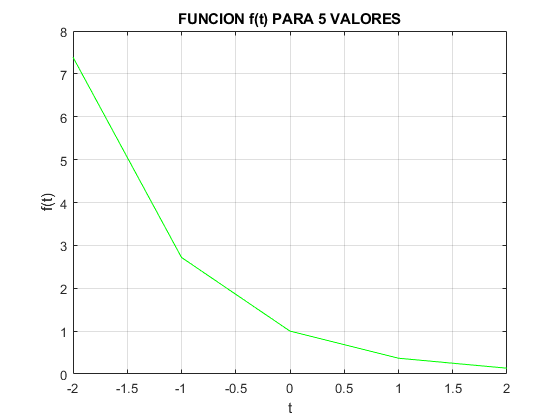

plot(t,f(t),'g');
xlabel("t"); ylabel("f(t)"); grid;
title('FUNCION f(t) PARA 5 VALORES');

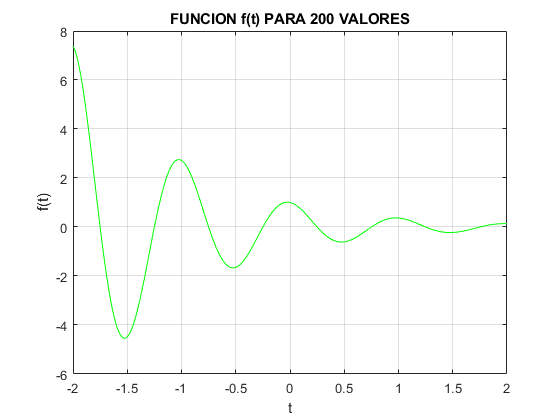

% Podemos hacer la grafica mas definida para f(t) si hacermos el vector t contenga mas
% valores en el mismo intervalo. Definiremos 200 valores en este intervalo:
t = (-2:0.01:2);
%GRAFICAMOS
plot(t,f(t),'g');
xlabel("t"); ylabel("f(t)"); grid;xlim([-2 2]);
title('FUNCION f(t) PARA 200 VALORES');

**• ENTREGABLE 2 - Problema 1.2-2 → Trasformaciones de Funciones**

clearvars;
clc;
clear;
syms t
syms k


$$\textrm{Dada}\;\textrm{la}\;\textrm{funcion}\;\textrm{de}\;\textrm{forma}\;\textrm{grafica},\textrm{resolver}\;\textrm{los}\;\textrm{incisos}:$$


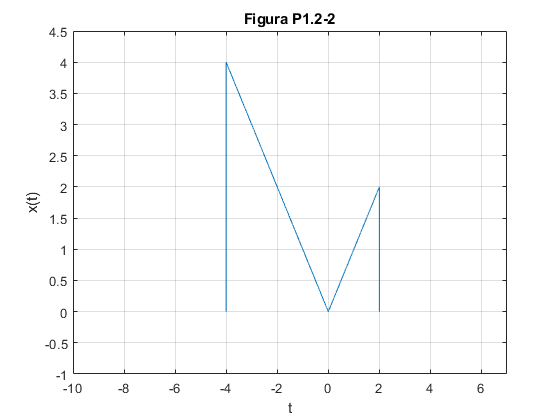

x=@(t)-1*t.*((t>=-4)&(t<0))+t.*((t>0)&(t<=2));
t=(-4.001:0.001:2.001);
plot(t,x(t));
title('Figura P1.2-2');
xlabel('t');ylabel('x(t)');grid on;
axis([-10 7 -1 4.5]);

**A → Traslacion Horizontal**


$$\textrm{Conociendo}\;x\left(t\right)\;\textrm{Bosquejar}\;x\left(t-4\right)$$


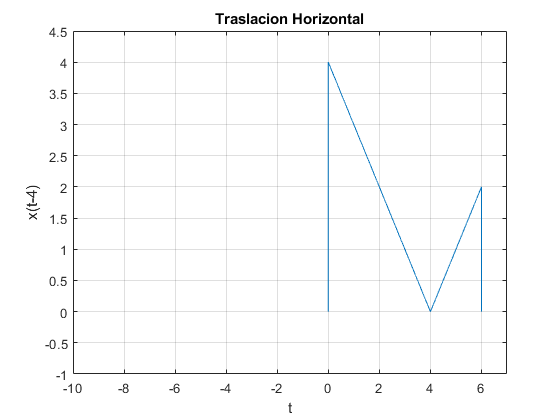

t=(-0.001:0.001:6.001);
plot(t,x(t-4));
xlabel('t');ylabel('x(t-4)');grid on;title('Traslacion Horizontal');
axis([-10 7 -1 4.5]);

**B → Escalamiento Horizontal**


$$\textrm{Conociendo}\;x\left(t\right)\;\textrm{Bosquejar}\;x\left(\frac{t}{1\ldotp 5}\right)$$


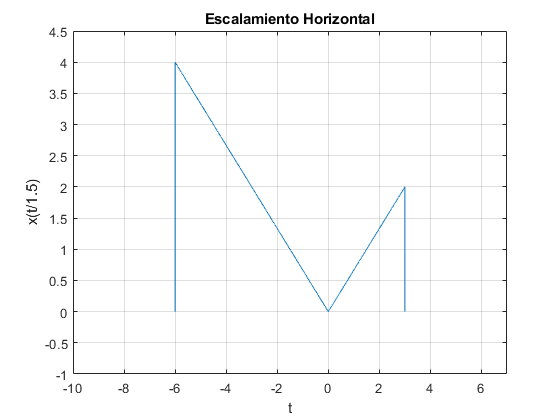

t=(-6.001:0.001:3.001);
plot(t,x(t/1.5));
xlabel('t');ylabel('x(t/1.5)');grid on;title('Escalamiento Horizontal');
axis([-10 7 -1 4.5]);

**C → Inversion Horizontal**


$$\textrm{Conociendo}\;x\left(t\right)\;\textrm{Bosquejar}\;x\left(-t\right)$$


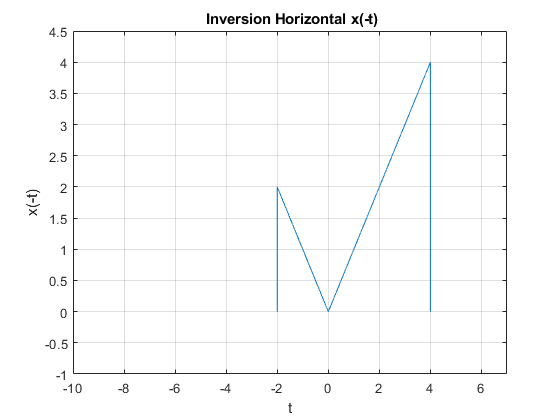

t=(-2.001:0.001:4.001);
plot(t,x(-t));
xlabel('t');ylabel('x(-t)');grid on;title(' Inversion Horizontal x(-t)');
axis([-10 7 -1 4.5]);

**D → Compresion y Traslacion Horizontal**


$$\textrm{Conociendo}\;x\left(t\right)\;\textrm{Bosquejar}\;x\left(2t-4\right)$$


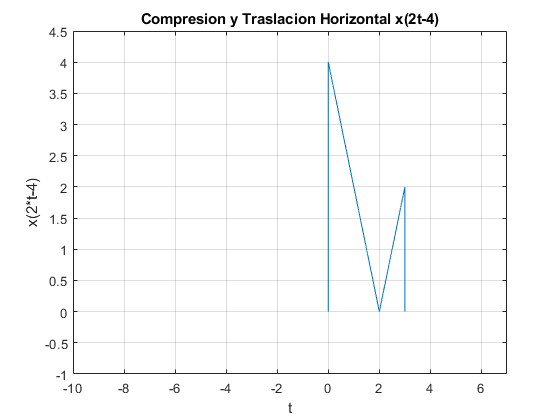

t=(-0.001:0.001:3.001);
plot(t,x(2*t-4));
xlabel('t');ylabel('x(2*t-4)');grid on;title('Compresion y Traslacion Horizontal x(2t-4)');
axis([-10 7 -1 4.5]);

**E → Inversion y Traslacion Horizontal**


$$\textrm{Conociendo}\;x\left(t\right)\;\textrm{Bosquejar}\;x\left(2-t\right)$$
 

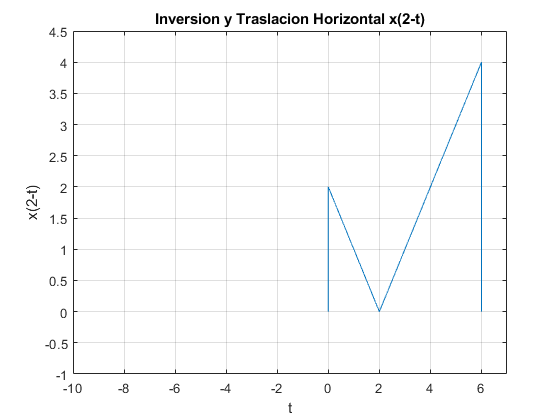

t=(-0.001:0.001:6.001);
plot(t,x(2-t));
xlabel('t');ylabel('x(2-t)');grid on;title('Inversion y Traslacion Horizontal x(2-t)');
axis([-10 7 -1 4.5]);

**• ENTREGABLE 3 - Energia de Señales continuas → Operaciones con señales**

[Graficas en Desmos](https://www.desmos.com/calculator/c81bvkoabx)

- Find the energies of the signals illustrated in Fig. P1.1-1.

- Comment on the effect on energy of sign change, time shifting, or doubling of the signal. 

- What is the effect on the energy if the signal is multiplied by k?

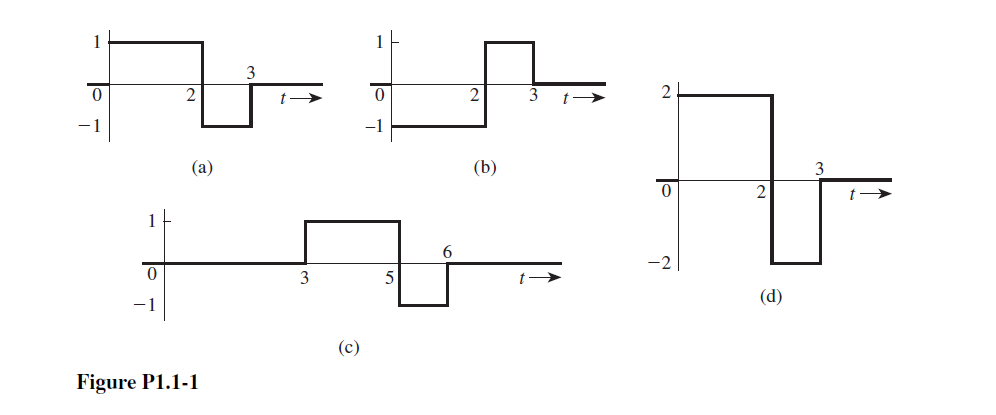

clearvars;
clc;
clear;
syms t
syms k
x=(0:0.01:6);

**A → Energia señal Original**

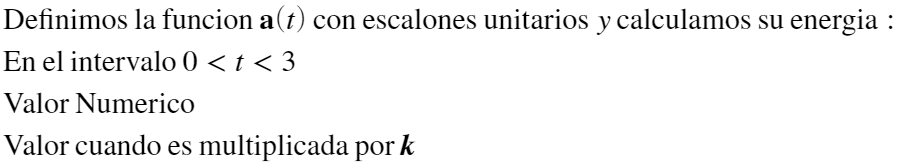

a(t)=(heaviside(t)-heaviside(t-2))-heaviside(t-2)+heaviside(t-3)

$$a(t) = \mathrm{heaviside}\left(t-3\right)-2\,\mathrm{heaviside}\left(t-2\right)+\mathrm{heaviside}\left(t\right)$$

fa = @(t) a(t);
Norma=a(t)*a(t);
Ea=int(Norma,t,0,3)

$$Ea = 3$$

Eak=int(k*Norma,t,0,3)

$$Eak = 3\,k$$

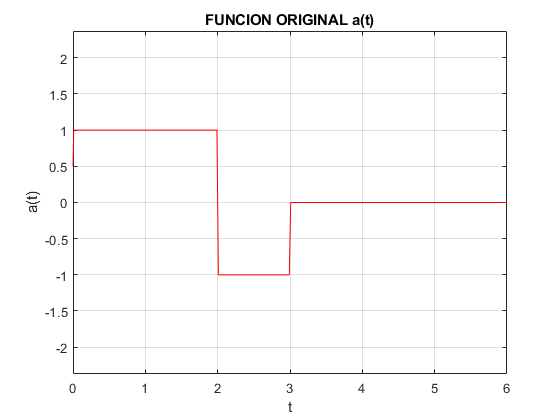

plot(x,fa(x),'r');xlabel("t"); ylabel("a(t)"); grid;axis equal;
title('FUNCION ORIGINAL a(t)');

**B → Energia señal Invertida **

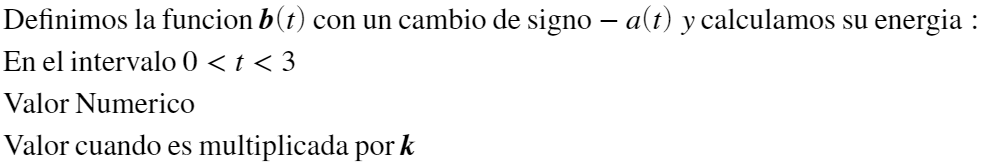

b(t)=-a(t)

$$b(t) = 2\,\mathrm{heaviside}\left(t-2\right)-\mathrm{heaviside}\left(t-3\right)-\mathrm{heaviside}\left(t\right)$$

fb = @(t) b(t);
Norma=b(t)*b(t);
Eb=int(Norma,t,0,3)

$$Eb = 3$$

Ebk=int(k*Norma,t,0,3)

$$Ebk = 3\,k$$

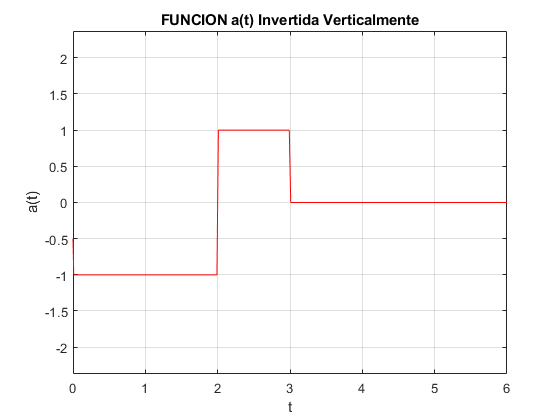

plot(x,fb(x),'r');xlabel("t"); ylabel("a(t)"); grid;axis equal;
title('FUNCION a(t) Invertida Verticalmente');

**C → Energia señal Trasladada**

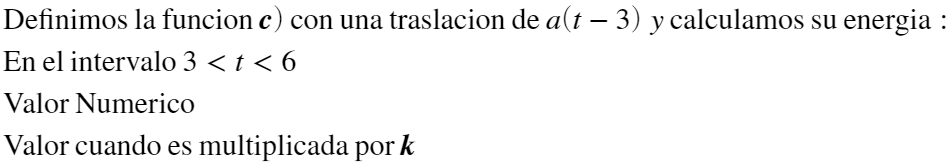

c(t)=a(t-3)

$$c(t) = \mathrm{heaviside}\left(t-3\right)-2\,\mathrm{heaviside}\left(t-5\right)+\mathrm{heaviside}\left(t-6\right)$$

fc = @(t) c(t);
Norma=c(t)*c(t);
Ec=int(Norma,t,3,6)

$$Ec = 3$$

Eck=int(k*Norma,t,3,6)

$$Eck = 3\,k$$

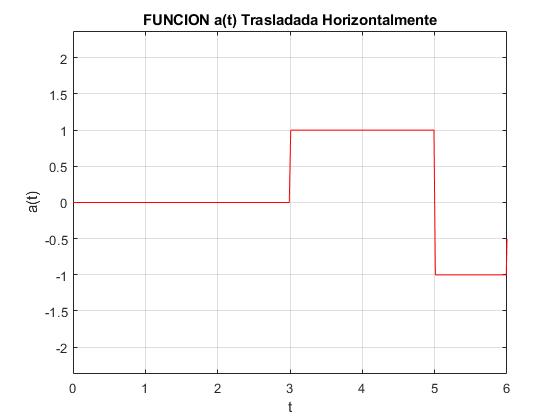

plot(x,fc(x),'r');xlabel("t"); ylabel("a(t)"); grid;axis equal;
title('FUNCION a(t) Trasladada Horizontalmente');

**D → Energia señal Escalada**

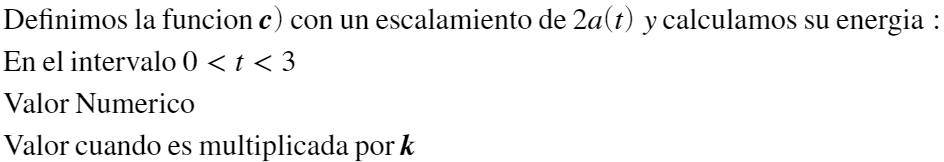

d(t)=2*a(t)

$$d(t) = 2\,\mathrm{heaviside}\left(t-3\right)-4\,\mathrm{heaviside}\left(t-2\right)+2\,\mathrm{heaviside}\left(t\right)$$

fd = @(t) d(t);
Norma=d(t)*d(t);
Ed=int(Norma,t,0,3)

$$Ed = 12$$

Edk=int(k*Norma,t,0,3)

$$Edk = 12\,k$$

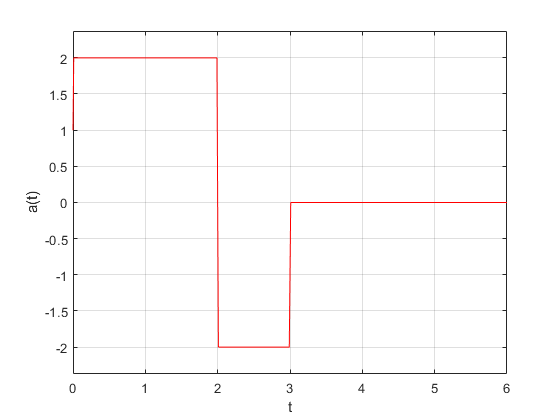

plot(x,fd(x),'r');xlabel("t"); ylabel("a(t)");grid on;axis equal;

**Conclusiones**

**De forma general podemos decir:**

Cuando el **signo cambia**:

**• El cambio de signo en la Señal de energia no importa ya que cuando es negativa y se saca su norma el signo desaparece.**

Cuando la Senal se **traslada**:

**• Solo se traslada la energia por tanto el valor de la funcion sigue siendo el mismo pero en otro intervalo de tiempo**

Cuando la Señal se **escala**

 **•En este caso la Señal de multiplica por el cuadrado del escalamiento****• ENTREGABLE 4 - Grafica con series→ Funciones Anonimas Programadas**

clearvars;
clc;
clear;
syms t
syms k

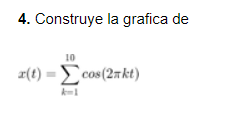

f=@(t)(cos(2*pi*t)+cos(4*pi*t)+cos(6*pi*t)+cos(8*pi*t)+cos(10*pi*t)+cos(12*pi*t)+cos(14*pi*t)+cos(16*pi*t)+cos(18*pi*t)+cos(20*pi*t));
t=0;f(t)

ans = 10

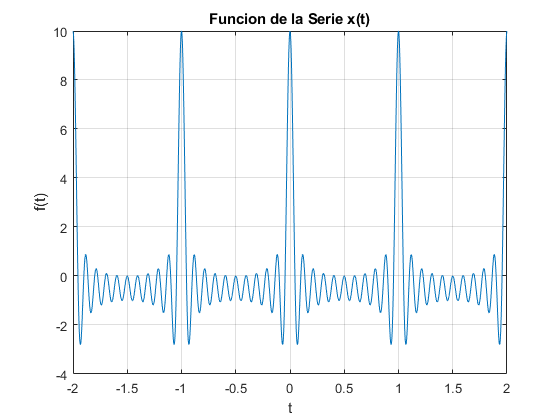

t=(-2:0.001:2);
plot(t,f(t));
xlabel('t');ylabel('f(t)');grid;
title('Funcion de la Serie x(t)');

**• ENTREGABLE 5 - Problema 1.11-3 → ****Funciones Complejas y Operaciones en Argumento t**

clearvars;
clc;
clear;
syms t
syms k

**A → Grafica Real Vs Imaginaria**


$$\begin{array}{l}
\textrm{Define}\;a\;x\left(t\right)=e^{t\left(1+\textrm{j2}\pi \right)} u\left(-t\right)\;y\;\textrm{ademas}\;a\;y\left(t\right)\;\textrm{como}\;\textrm{Re}\left\lbrace 2x\left(\frac{-5-t}{2}\right)\right\rbrace \;\;\\
\textrm{Grafica}\;\textrm{Re}\left\lbrace x\left(t\right)\right\rbrace \;\textrm{Vs}\;\textrm{Im}\left\lbrace x\left(\textrm{at}\right)\;\;\;\textrm{Cuando}\;\;a=0\ldotp 5\;;1\;;2\;\;\;\textrm{Para}\;:\;-10\le t\le 10\right\rbrace 
\end{array}$$


Para este ejercicio necesitamos definir al escalon unitario 

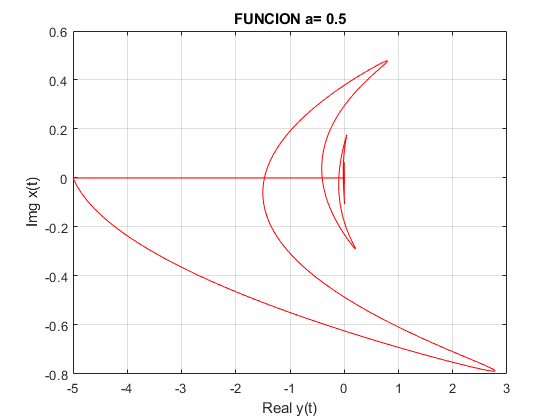

u = @(t) 1.0.*(t>=0);
x = @(t) exp((t)*(1+2*pi*1i)).*u(-t);
y = @(t) real(2*x(t).*((-5-t)/(2)));
% a=[0.5 1 2];
a=[0.5,1,2];
t=(-10:0.01:10);
imx1=imag(x(a(1).*t));
imx2=imag(x(a(2).*t));
imx3=imag(x(a(3).*t));
% hold on;
plot(y(t),imx1,'r');xlabel("Real y(t)"); ylabel("Img x(t)"); title('FUNCION a= 0.5');grid on;

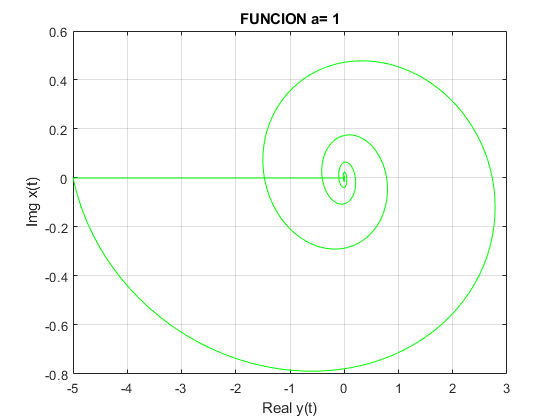

figure;
plot(y(t),imx2,'g');xlabel("Real y(t)"); ylabel("Img x(t)"); title('FUNCION a= 1');grid on;

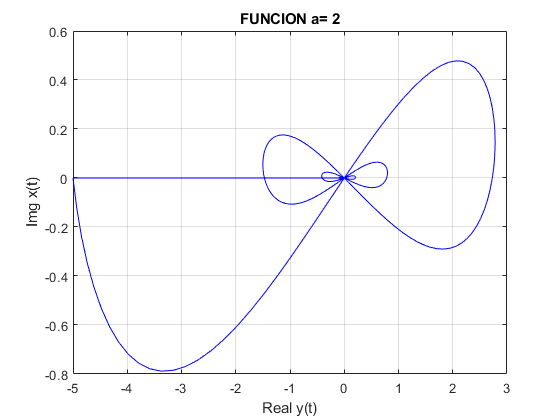

figure;
plot(y(t),imx3,'b');xlabel("Real y(t)"); ylabel("Img x(t)"); title('FUNCION a= 2');grid on;

figure;

**B → Grafica y Discontinuidad**


$$\textrm{Grafica}\;\;y\left(t\right)\;\textrm{como}\;\textrm{Re}\left\lbrace 2x\left(\frac{-5-t}{2}\right)\right\rbrace \;\textrm{para}-10\le y\le 10\;y\;\textrm{analiticamente}\;\textrm{determina}\;\textrm{adonde}\;\textrm{hay}\;\textrm{una}\;\textrm{discontinuidad}$$


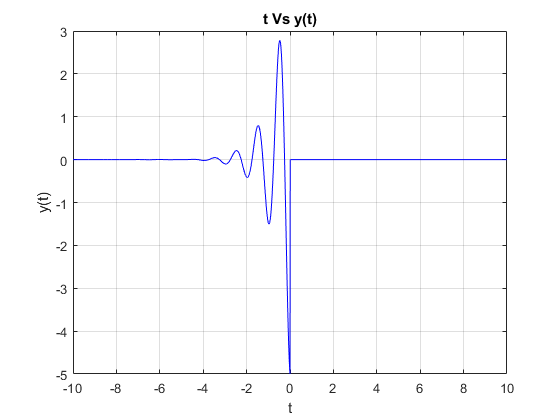

cla; 
plot(t,y(t),'b');xlabel("t");
ylabel("y(t)"); title('t Vs y(t)');grid on;

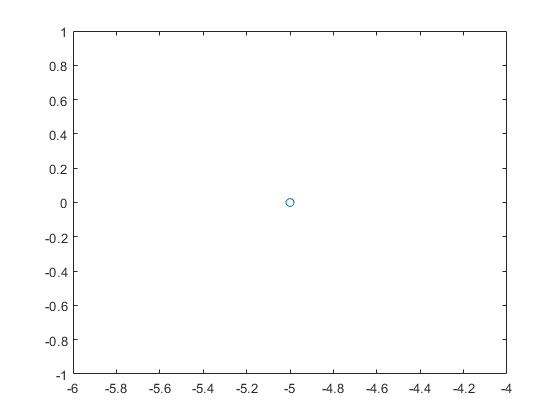

plot(-5,y(-5),'-o');

$\textrm{Analiticamente}\;\textrm{podemos}\;\textrm{decir}\;\textrm{que}\;\textrm{la}\;\textrm{grafica}\;\textrm{no}\;\textrm{esta}\;\textrm{definida}\;\textrm{en}\;t=-5\;\textrm{ya}\;\textrm{que}\;\textrm{ahi}\;\textrm{se}\;\textrm{indetermina}\;\textrm{para}\;\left(\frac{-5-t}{2}\right)$**C → Energia señal x(t) Valor Numerico**

Determina la señar de la funcion compleja x(t)

% syms t
% Norma=(real(x))^2+(imag(x))^2;
% Ex=int(Norma,t,-10,10)

D → Energia señal y(t) Valor Numerico

syms t
Norma=y(t)*y(t);
Ey=int(Norma,t,-10,10)

$$Ey = \mathrm{NaN}$$

**E → Grafica compleja de x(t) **


$$\textrm{Grafica}\;x\left(t\right)=e^{t\left(1+\textrm{j2}\pi \right)} u\left(-t\right)\;\textrm{para}-10\le t\le 10$$


x = @(t) exp((t)*(1+2*pi*1i)).*u(-t)

x = function_handle with value:
    @(t)exp((t)*(1+2*pi*1i)).*u(-t)


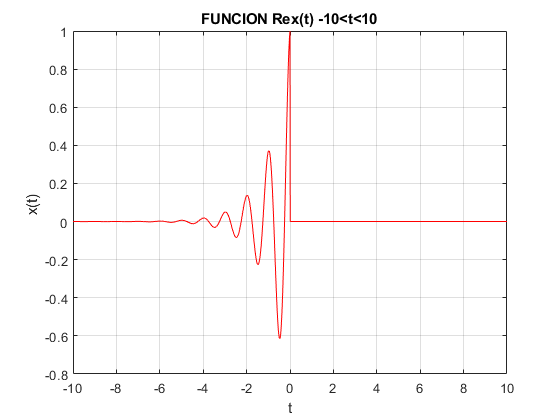

t=(-10:0.01:10);
plot(t,real(x(t)),'r');xlabel("t"); ylabel("x(t) "); title('FUNCION Re{x(t)} -10<t<10');grid on;

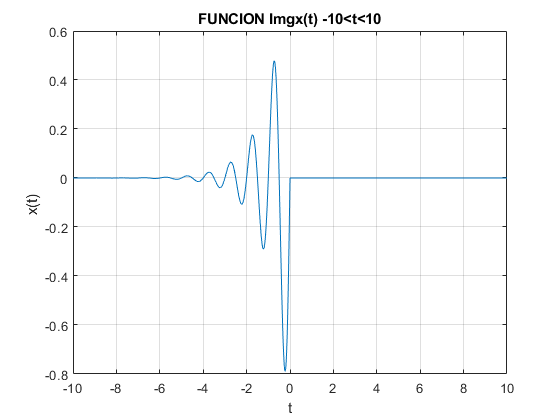

plot(t,imag(x(t)));xlabel("t"); ylabel("x(t) "); title('FUNCION Img{x(t)} -10<t<10');grid on;

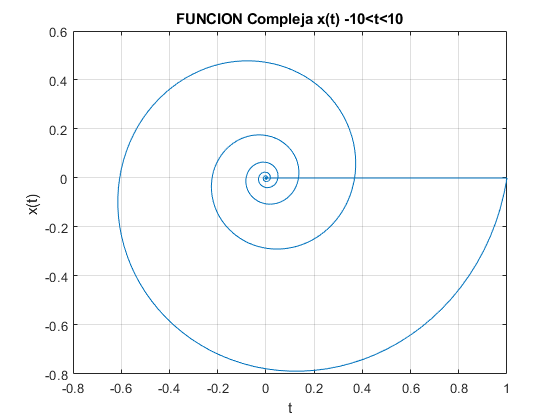

plot(real(x(t)),imag(x(t)));xlabel("t"); ylabel("x(t) "); title('FUNCION Compleja {x(t)} -10<t<10');grid on;

**• ENTREGABLE 6 - App Matlab**

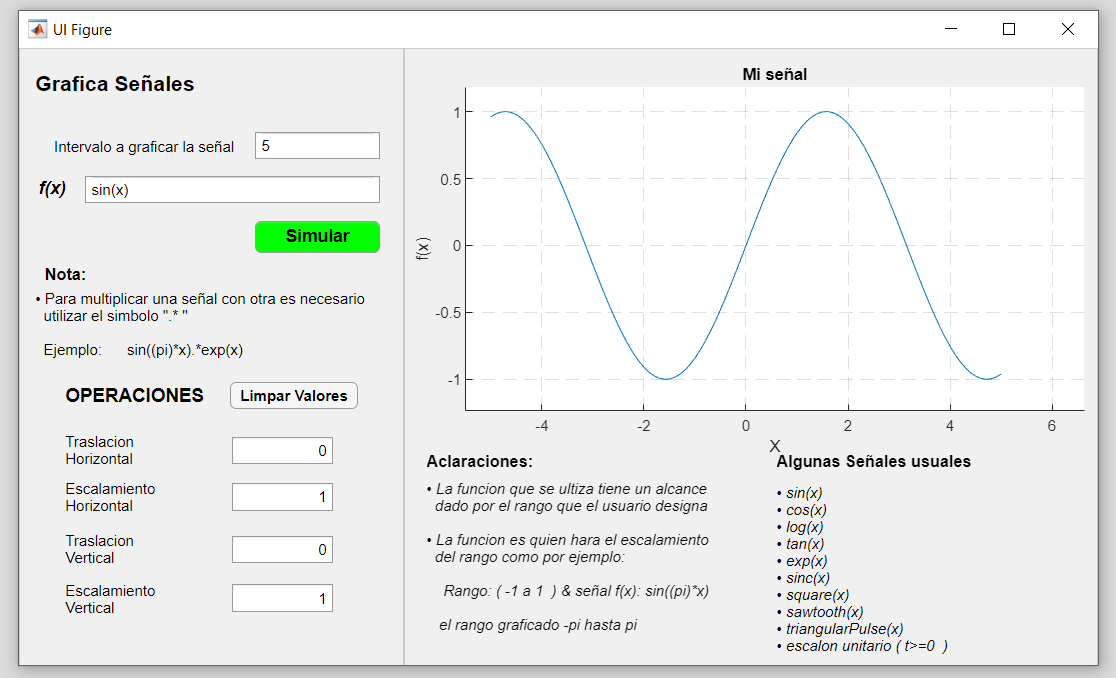

- Gráficar señales en tiempo continuo reales, el usuario ingresa la definición de la señal en el formato especifico

- El usuario puede definir el intervalo de la gráfica

- El usuario puede seleccionar el tipo de transformación (horizontal, vertical o combinación) que desee realizar a la señal, la app deberá mostrar la gráfica de esta transformación.

- Se adjunta una imagen de la app a la práctica, y el archivo de la app.

**Nota :**

- Para utilizar la app es Necesario descargarla en el siguiente link: [Descarga Archivo](https://drive.google.com/drive/folders/1zXbY_ZdLfVqVMGgR8Un2aAnn_Ftedbf1?usp=sharing)

- Para iniciar la app hay que abrir el archivo desde **  Home / Open y una ves en la ventana de appDesigner Pulsar el Run**